`例 求向量序列的最大值。`  

% A、 B两个向量
A = [2 3 7 16 0 1 8 12 -3 4];
B = [1 0 8 3 31 -1 16 2 9 10];
% 求向量A中的最大值
a = max(A)

a = 16

% 求A、 B中位置相同处的元素最大值
b= max(A,B)

b =      2     3     8    16    31     1    16    12     9    10


`例 求矩阵序列的最大值。`  

% D是矩阵
D = [1 4 13 9; 2 39 11 6; -1 2 8 17; 21 5 11 0]

D =      1     4    13     9
     2    39    11     6
    -1     2     8    17
    21     5    11     0


% 求D中的最大值
A= max(D,[ ],1)

A =     21    39    13    17


% 求D中沿着第2维的最大值
B= max(D,[ ],2)

B =     13
    39
    17
    21


% 求矩阵的最大值
[C, I] = max(D)

C =     21    39    13    17


I =      4     2     1     3


`例 求矩阵`**A**`的和。`  

clear all
clc;
% A为矩阵
A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


% 求和
B = sum(A)

B =     12    15    18


% 对第2维求和
C = sum(A, 2)

C =      6
    15
    24


% 设置不同的精度
B = sum(A,2,'double')

B =      6
    15
    24


C = sum(A,2,'native')

C =      6
    15
    24


`例 求矩阵`**A**`的积。`  

% A为矩阵
A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


% 求积
B = prod(A)

B =     28    80   162


% 对第2维求积
C = prod(A, 2)

C =      6
   120
   504


% 设置不同的精度
B = prod(A,2,'double')

B =      6
   120
   504


C = prod(A,2,'native')

C =      6
   120
   504


`例 求矩阵`**A**`的算术平均值。`  

%输入矩阵A
A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


%求矩阵A沿第1维的算术平均值
M1 = mean(A)

M1 =      4     5     6


%求矩阵A的沿第2维的算术平均值
M2 = mean(A,2)

M2 =      2
     5
     8


%求矩阵A的算术平均值
M3 = mean(mean(A))

M3 = 5

%还可以怎么算整个矩阵的平均值？


`例 求矩阵`**A**`的中值。`  

%输入矩阵A
A = [1 2 3; 4 2 4; 6 7 8]

A =      1     2     3
     4     2     4
     6     7     8


%求矩阵A沿第1维的中值
M1 = median(A)

M1 =      4     2     4


%求矩阵A的沿第2维的中值
M2 = median(A,2)

M2 =      2
     4
     7


%求矩阵A的中值
M3 = median(median(A))

M3 = 4

在疼痛研究中，麦吉尔疼痛问卷常用来评估疼痛的强度和质量。如图所示，该问卷中的疼痛分级指标（PRI）通过多个维度评估疼痛（i.e.,感觉项、情感项），每个维度小项的总分为该维度的疼痛评分。

在一项实验中，研究人员分别收集了30名被试的麦吉尔疼痛问卷。求：1）每个被试的PRI总分；2）所有被试PRI平均分；3）找到PRI分数最高的被试。

% 随机生成30名被试的PRI（15项）评分（30*15）
rng(666);
A = randi([0,3],[30 15]);
% 每个被试的PRI总分
PRI = sum(A,2)

PRI =     20
    21
    30
    21
    21
    16
    12
    12
    26
    19


% 平均分
PRI_s = mean(PRI)

PRI_s = 22.4000

% PRI分数最高的被试
[MaxVal,MaxI]=max(PRI)

MaxVal = 33

MaxI = 28


%问题：感觉项为11个，情感项为4个，请单独统计两个维度的总分、均值和最大值
PRI_f = sum(sum(A(:,1:11)))

PRI_f = 504

PRI_e = sum(sum(A(:,12:15)))

PRI_e = 168

mean_f = mean(mean(A(: , 1:11)))

mean_f = 1.5273

mean_e = mean(mean(A(: , 12:15)))

mean_e = 1.4000

[max_f, idx_f] = max(max(A(:, 1:11)))

max_f = 3

idx_f = 1

[max_e, idx_e] = max(max(A(:, 12:15)))

max_e = 3

idx_e = 1

`例 求矩阵`**A**`的累加和。`  

% 输入矩阵A
A = [1 2 3;4 5 6;7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


% 求矩阵A的沿第1伟的累加和
C = cumsum(A)

C =      1     2     3
     5     7     9
    12    15    18


% 求矩阵A的沿第2维的累加和
C1 = cumsum(A, 2)

C1 =      1     3     6
     4     9    15
     7    15    24


`例 求矩阵`**A**`的累乘积。`  

% 输入矩阵A
A = [1 2 3;4 5 6;7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


% 求矩阵A的沿第1维的累乘积
C = cumprod(A)

C =      1     2     3
     4    10    18
    28    80   162


% 求矩阵A的沿第2维的累乘积
C1 = cumprod(A, 2)

C1 =      1     2     6
     4    20   120
     7    56   504


`例 求向量`**X**`的标准方差。`  

% 输入向量X
X = [2 8 14 0 -7 9 1 21]

X =      2     8    14     0    -7     9     1    21


% 按公式（5-1）求向量X的标准方差
S = std(X)

S = 8.8479

% 按公式（5-2）求向量X的标准方差
S1 = std(X, 1)

S1 = 8.2765

`例 求向量`**Y1**`和`**Y2**`的相关系数。`  

%Y1和Y2为两个向量
Y1 = [1 5 8 12 6 2]

Y1 =      1     5     8    12     6     2


Y2 = [2 6 3 7 9 11]

Y2 =      2     6     3     7     9    11


% 求Y1和Y2的相关系数
R = corrcoef(Y1, Y2)

R =     1.0000    0.0096
    0.0096    1.0000


`例 求矩阵`**X**`的相关系数。`  

%创建一个随机的矩阵
X = rand(10,5)

X =     0.3484    0.8805    0.8571    0.3838    0.1403
    0.5173    0.5277    0.0677    0.4202    0.7596
    0.5313    0.4774    0.4229    0.8071    0.4893
    0.6707    0.3053    0.5442    0.6414    0.2827
    0.0681    0.2814    0.1432    0.3636    0.7597
    0.4778    0.4519    0.4154    0.9401    0.2997
    0.5577    0.4561    0.2537    0.5883    0.6439
    0.0229    0.5476    0.8488    0.6722    0.5188
    0.9020    0.2558    0.5149    0.1621    0.6337
    0.1355    0.1883    0.5523    0.2394    0.6599


% 求X的相关系数
[R, P] = corrcoef(X)

R =     1.0000   -0.1070   -0.1851   -0.0032   -0.1425
   -0.1070    1.0000    0.3867    0.2452   -0.5492
   -0.1851    0.3867    1.0000    0.0252   -0.6614
   -0.0032    0.2452    0.0252    1.0000   -0.4395
   -0.1425   -0.5492   -0.6614   -0.4395    1.0000


P =     1.0000    0.7687    0.6086    0.9931    0.6945
    0.7687    1.0000    0.2696    0.4948    0.1001
    0.6086    0.2696    1.0000    0.9449    0.0373
    0.9931    0.4948    0.9449    1.0000    0.2038
    0.6945    0.1001    0.0373    0.2038    1.0000


%创建一个随机的矩阵
Y = rand(10,5)

Y =     0.2552    0.3263    0.4721    0.7271    0.3931
    0.5895    0.2131    0.1562    0.9147    0.4457
    0.1215    0.4595    0.5835    0.6847    0.4421
    0.0496    0.0658    0.9358    0.7159    0.1743
    0.1953    0.4361    0.5470    0.8299    0.3645
    0.7281    0.9254    0.3846    0.2327    0.0326
    0.7800    0.8969    0.5177    0.4255    0.1723
    0.9072    0.5827    0.4087    0.2660    0.5996
    0.1799    0.5589    0.0714    0.7973    0.1763
    0.6853    0.4198    0.2463    0.1142    0.9912


% 求X的相关系数
[R, P] = corrcoef(X,Y)

R =     1.0000   -0.0918
   -0.0918    1.0000


P =     1.0000    0.5260
    0.5260    1.0000


[R, P] = corr(X)

函数或变量 'corr' 无法识别。

`【例】` `为开发一种药物`X`可治疗慢性疼痛，目前正处于疗效测试阶段，病人服用药物天数最长达到半年，探究服用药物时长与疼痛综合评分（`VAS`）之间的关系，总共招募了约`50`名实验者。`

%读取文件
load medicine_x.mat
time = dataset(1,1:50);
pain_rating = dataset(2,1:50);

%计算相关系数
[R,P] = corrcoef(time, pain_rating)

R =     1.0000   -0.5898
   -0.5898    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


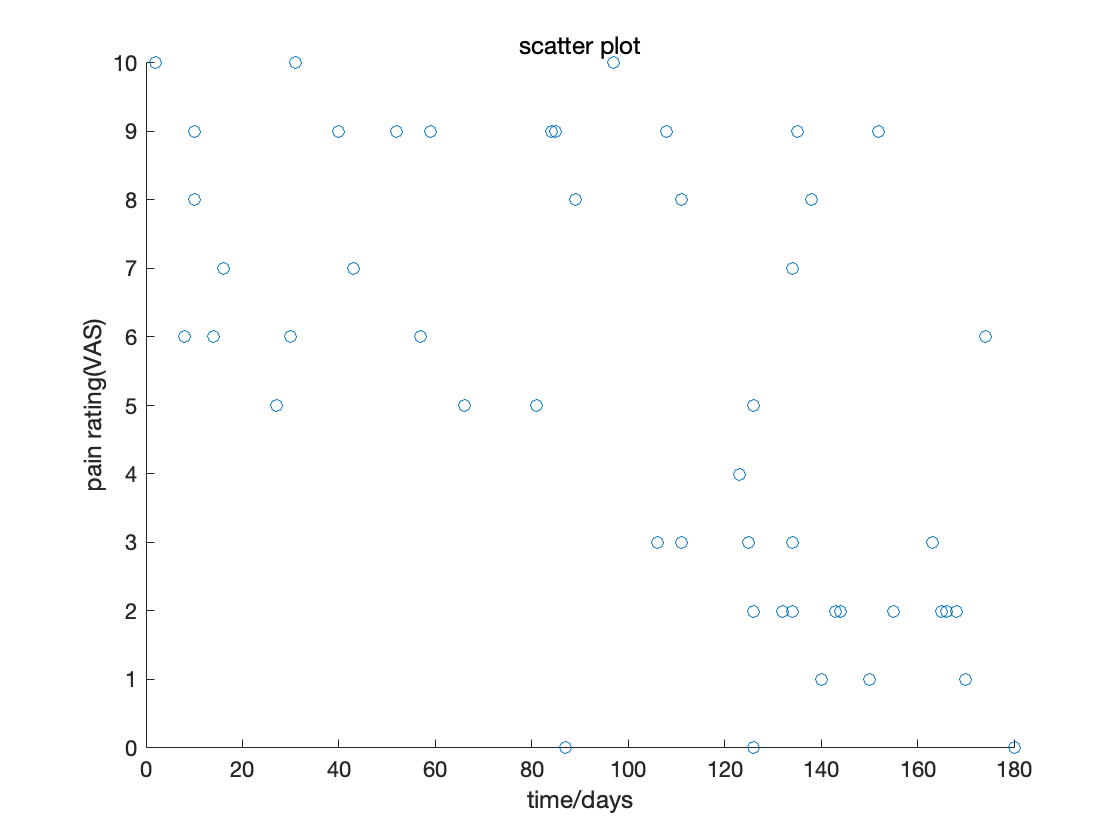


%作图
scatter(time,pain_rating);
xlabel('time/days');
ylabel('pain rating(VAS)');
title('scatter plot');

`例 对下面给出的数据进行一维数据插值。`  

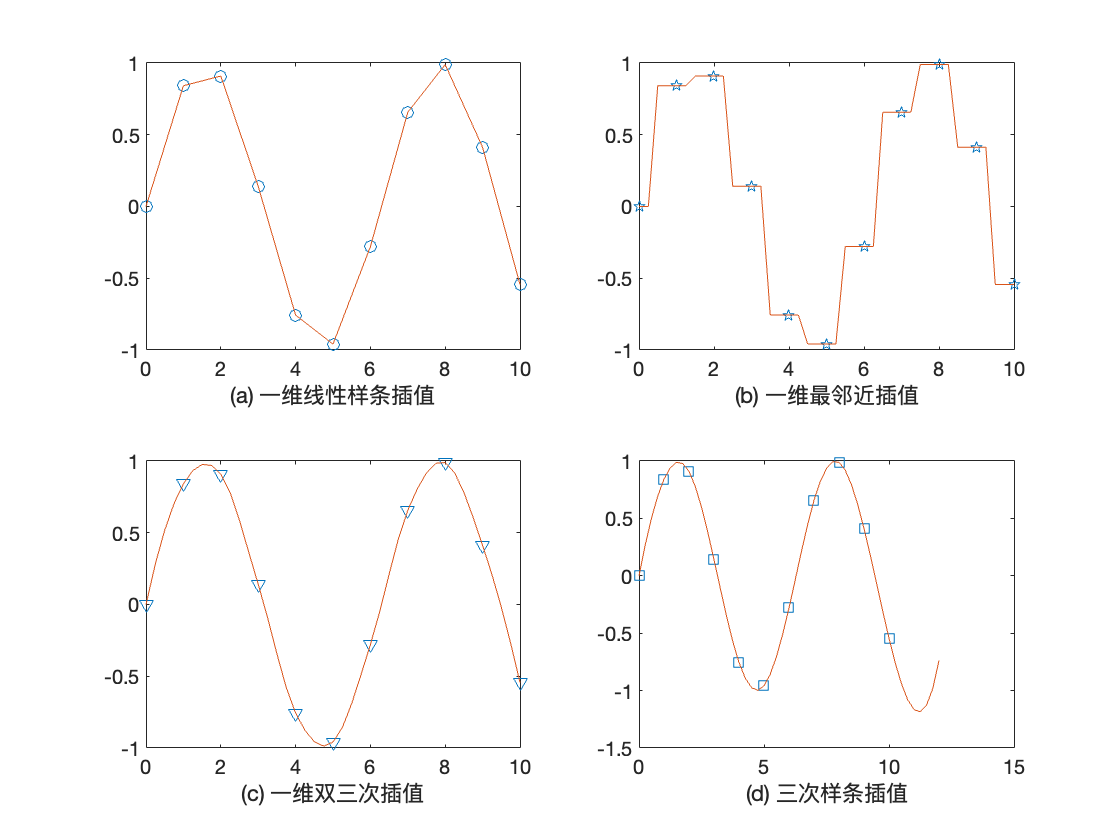

% 数据准备
x = 0:10;
y = sin(x);
xi = 0:.25:12;
% 线性插值
y1 = interp1(x, y, xi);
subplot(2, 2, 1)
plot(x, y, 'o', xi, y1)
xlabel('(a) 一维线性样条插值')
% 最邻近线性插值
y2 = interp1(x, y, xi, 'nearest');
subplot(2, 2, 2)
plot(x, y, 'p', xi, y2)
xlabel('(b) 一维最邻近插值')
% 双三次插值
y3 = interp1(x, y, xi, 'cubic') ;
subplot(2, 2, 3)
plot(x, y, 'v', xi, y3)
xlabel('(c) 一维双三次插值')
%样条插值
y4 = interp1(x, y, xi, 'spline');
subplot(2, 2, 4)
plot(x, y, 's', xi, y4)
xlabel('(d) 三次样条插值')

例 在疼痛实验中，环境温度对疼痛感知有一定的影响。在某次实验中，研究人员在实验开始后的12个小时内，每隔半个小时记录了实验室的环境温度，用3次样条插值分别求该实验中每隔15分钟的近似环境温度。

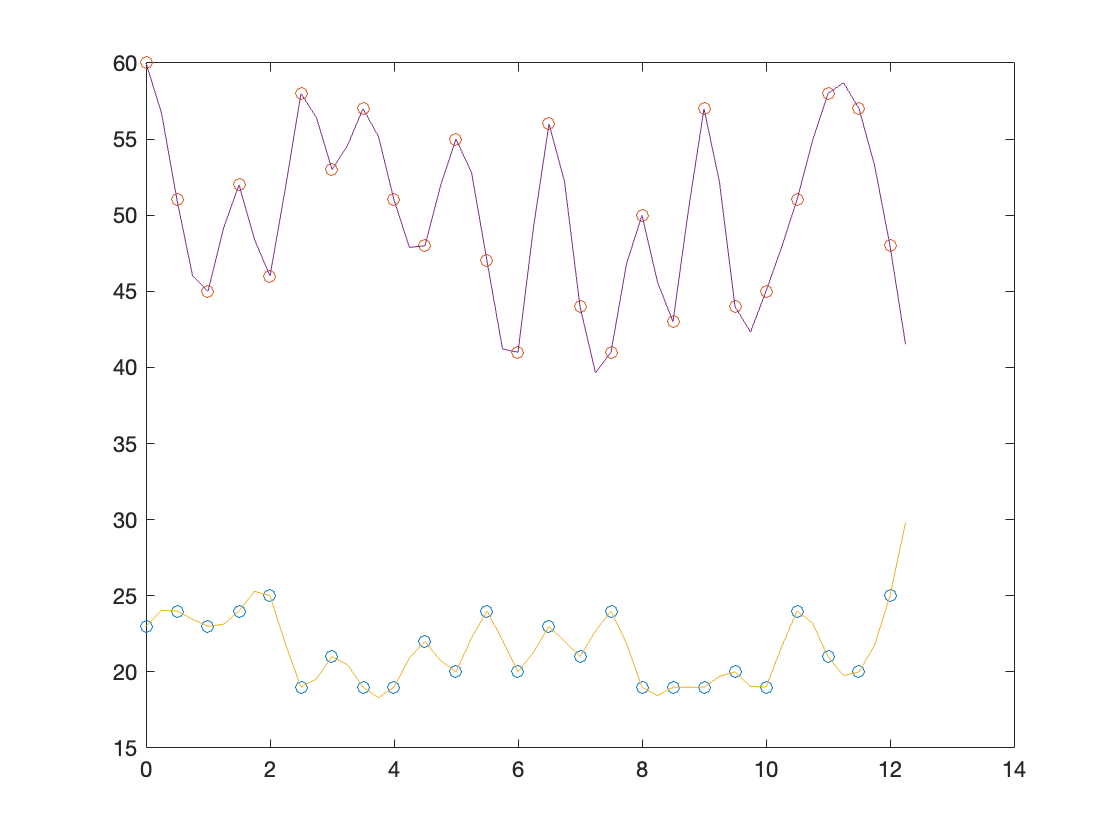

% 设时间变量h为一行向量，温度变量t为一个两列矩阵，其中第一列存放环境温度，第二列储存环境湿度。命令如下：
h =0:0.5:12;
rng(666);
temp = randi([19,25],[1,25]);
humi = randi([40,60],[1,25]);
A = [temp;humi]';
% 用3次样条插值计算
XI =0:0.25:12.25;
YI=interp1(h,A,XI,'spline');
figure, plot(h,A,'o',XI,YI)

`例 某实验对一根长`**10**`米的钢轨进行热源的温度传播测试。用`**x**`表示测量点`**0:2.5:10(**`米`**)**`，用`**h**`表示测量时间`**0:30:60(**`秒`**)**`，用`**T**`表示测试所得各点的温度`**(℃)**`。试用线性插值求出在一`

`分钟内每隔`**20**`秒、钢轨每隔`**1**`米处的温度`**TI**`。`

**MATLAB**`代码如下：`  

x=0:2.5:10;
h=[0:30:60]';
T=[95,14,0,0,0;88,48,32,12,6;67,64,54,48,41];
xi=[0:10];
hi=[0:20:60]';
TI=interp2(x,h,T,xi,hi)

TI =    95.0000   62.6000   30.2000   11.2000    5.6000         0         0         0         0         0         0
   90.3333   68.8667   47.4000   33.6000   27.4667   21.3333   16.0000   10.6667    7.2000    5.6000    4.0000
   81.0000   69.9333   58.8667   50.5333   44.9333   39.3333   33.2000   27.0667   22.7333   20.2000   17.6667
   67.0000   65.8000   64.6000   62.0000   58.0000   54.0000   51.6000   49.2000   46.6000   43.8000   41.0000


错误使用 plot3
向量长度必须相同。

`例 离散傅里叶变换示例。`  

N = 40;
n = 0:N-1;
k = 0:N-1;
%构建一个离散序列
x = [ones(1,5),zeros(1,N-5)];
%DFT变换
XK = dft(x,N);

函数或变量 'dft' 无法识别。

%求频谱值
Pinup = abs(XK);
subplot(1,2,1)
stem(n,x)
title('时域离散波形')
subplot(1,2,2)
stem(k,pinpu)
title('频谱波形')

`例 ``有一信号`**x**`由两种不同频率的正弦信号混合而成，且受零均值随机噪声的干扰，现通过得到信号的`**DFT**`，确定出信号的频率及其强度关系。`

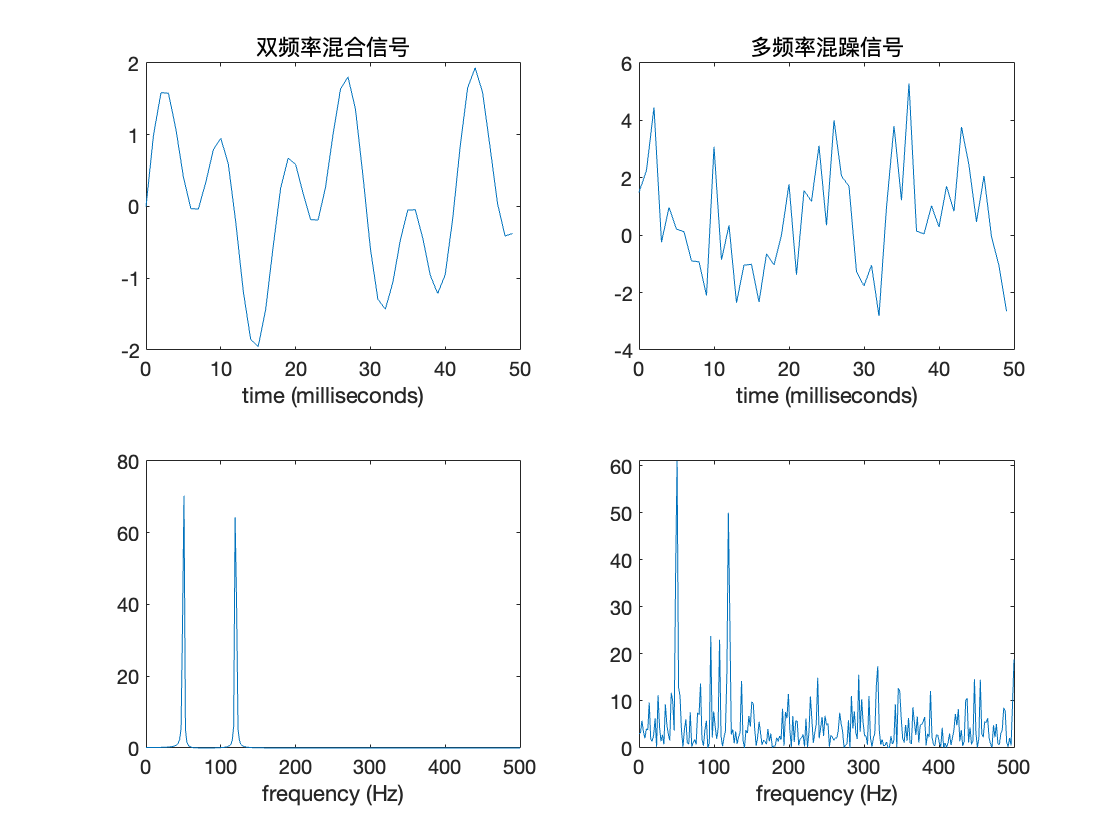

% 先创建一混合频率的正弦信号
t = 0:0.001:0.6;
x = sin(2*pi*50*t) + sin(2*pi*120*t);
% 加上受零均值随机噪声
y = x + 2*randn(size(t));
figure, subplot(221)
plot(1000*t(1:50), x(1:50))
title('双频率混合信号')
xlabel('time (milliseconds)')
subplot(2,2,2)
plot(1000*t(1:50), y(1:50))
title('多频率混躁信号')
xlabel('time (milliseconds)')

%计算x函数的傅里叶变换
Y = fft(x, 512);
%计算功率谱密度
Pyy = Y.* conj(Y) / 512;
f = 1000*(0:256)/512;
subplot(2,2,3)
plot(f, Pyy(1:257))
xlabel('frequency (Hz)')

%计算y函数的傅里叶变换
Y = fft(y, 512);
%计算功率谱密度
Pyy = Y.* conj(Y) / 512;
f = 1000*(0:256)/512;
subplot(2,2,4)
plot(f, Pyy(1:257))
xlabel('frequency (Hz)')

`例 用三阶多项式拟合下面的数据，并画出拟合曲线`  

%拟合数据x、 y
x = [1 2 3 4 5]

x =      1     2     3     4     5


y = [5.5 43.1 128 290.7 498.4]%用多项式拟合数据x和y

y =     5.5000   43.1000  128.0000  290.7000  498.4000


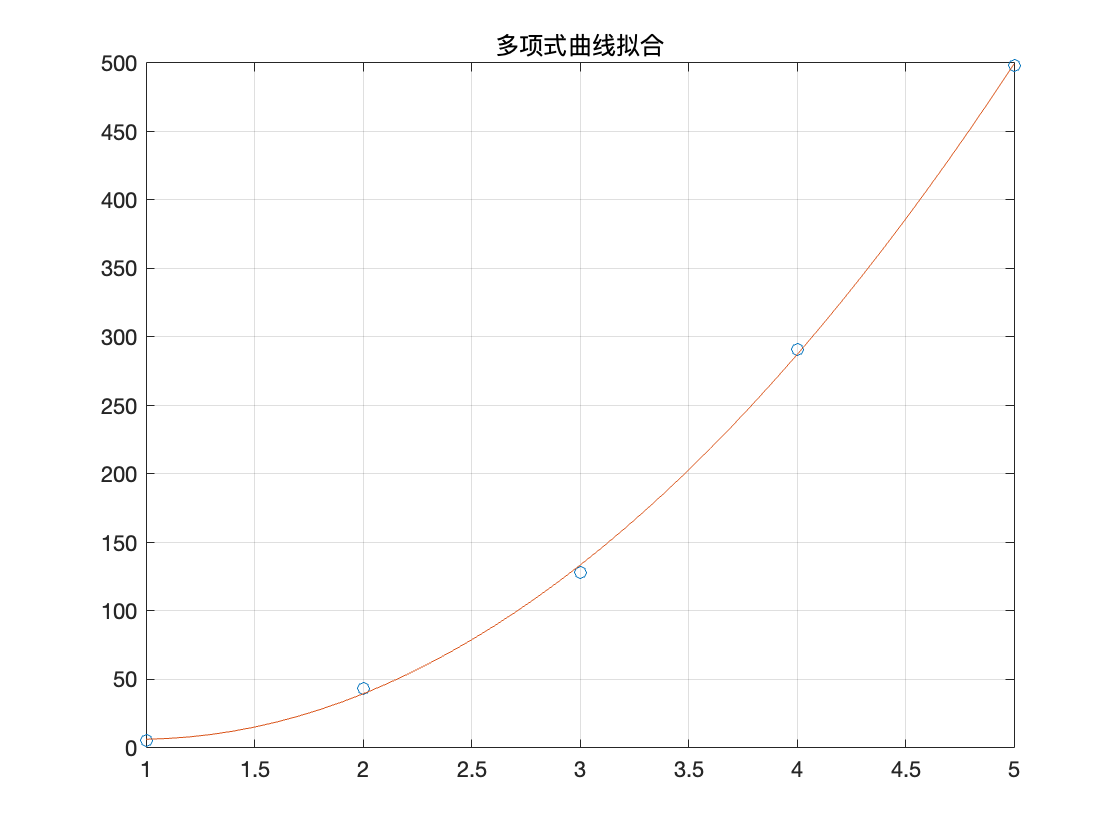

p = polyfit(x,y,3);
%利用polyval函数计算拟合的多项式系数p在给定数据x处的y值
x1 = 1:0.1:5;
y1 = polyval(p,x1);
% 绘制曲线图
figure
plot(x,y,'o',x1,y1)
grid on
title('多项式曲线拟合')

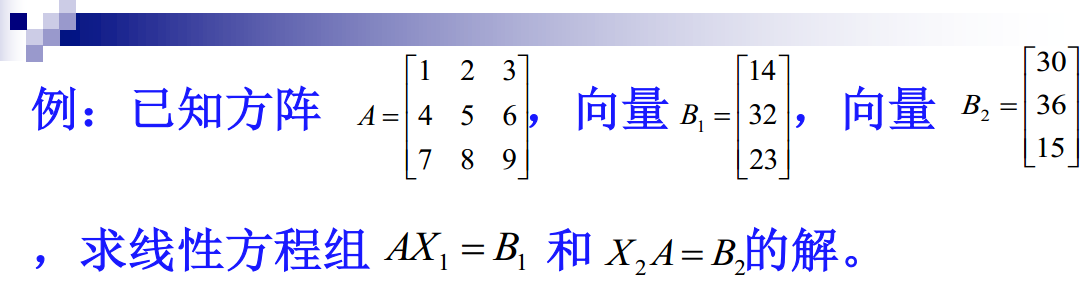

% 创建方阵A
A = [1 2 3; 4 5 6; 7 8 0]

A =      1     2     3
     4     5     6
     7     8     0


% 创建列向量B
B1 = [14; 32; 23]

B1 =     14
    32
    23


B2 = [30 36 15]

B2 =     30    36    15


% 进行直接求解
X1 = A\B1

X1 =     1.0000
    2.0000
    3.0000


X2 = B2/A

X2 =     1.0000    2.0000    3.0000


【例】过去的研究发现负性情绪可以影响疼痛感知。但是，负性情绪与疼痛之间的关系是非单调的，低到中度的负性情绪引起痛觉敏化，而强烈的负性情绪会抑制痛觉感知（Meagher et al., 2001）。在一项负性情绪和疼痛感知的实验中，被试观看一张负性图片（例如痛苦的表情）后接受热刺激，然后对两者在0~10分之间评分。用不同阶多项式拟合该实验模拟数据，并画出拟合曲线。

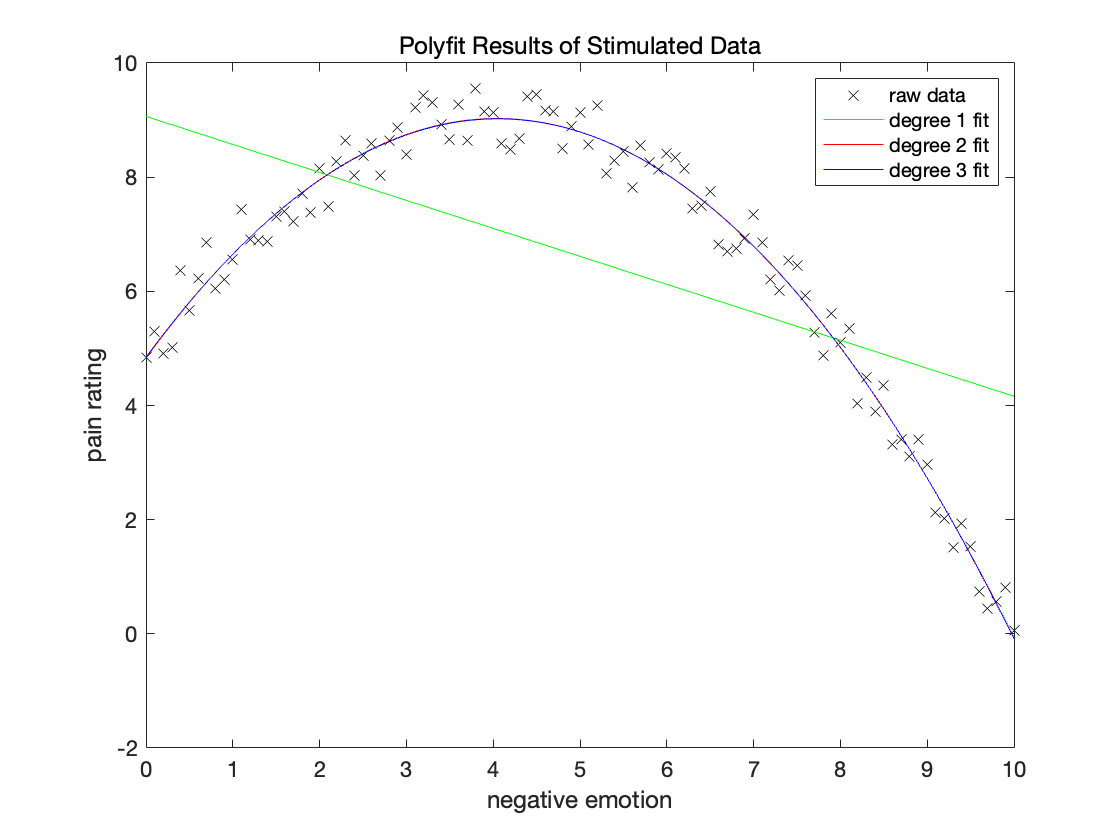

load simulatedData.mat
x=(simulatedData(1,:));
y=(simulatedData(2,:));
% 用三种多项式拟合数据x和y
coef1 = polyfit(x,y,1);
coef2 = polyfit(x,y,2);
coef3 = polyfit(x,y,3);
% 利用polyval函数计算拟合的多项式系数p在给定数据x处的y值
yfit1 = polyval(coef1,x);
yfit2 = polyval(coef2,x);
yfit3 = polyval(coef3,x);
% 绘制曲线图
figure, plot(x,y,'kx',x,yfit1,'g',x,yfit2,'r',x,yfit3,'b')
xlabel('negative emotion'),ylabel('pain rating'), title('Polyfit Results of Stimulated Data')
legend('raw data','degree 1 fit','degree 2 fit','degree 3 fit');

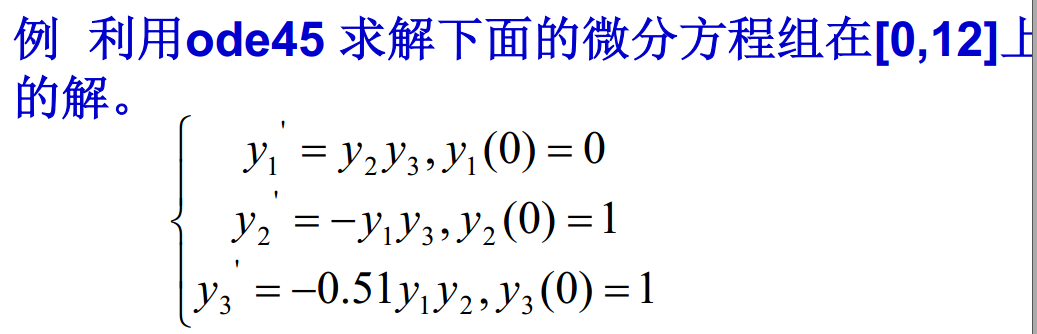

tspan = [0,12];
options = odeset('RelTol',1e-4,'AbsTol',[1e-4 1e-4 1e-5]);
y0 = [0;1;1];
[T,Y] = ode45('fun',tspan,y0,options);

错误使用 feval
函数或变量 'fun' 无法识别。

出错 odearguments (第 90 行)
f0 = feval(ode,t0,y0,args{:});   % ODE15I sets args{1} to yp0.

出错 ode45 (第 115 行)
  odearguments(FcnHandlesUsed, solver_name, ode, tspan, y0, options, varargin);

figure(1)
plot(T,Y(:,1),'b-',T,Y(:,2),'k-.',T,Y(:,3),'r.')

    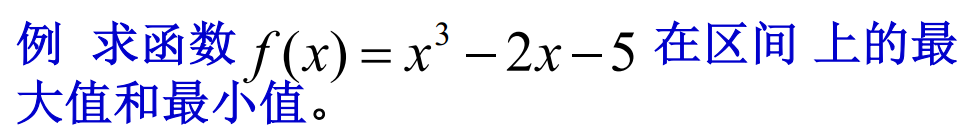

% 调用fminbnd函数分别求最小值和最大值
[x1,zuixiao] = fminbnd(@xmin1,0,5)
[x2,zuixiao1] = fminbnd(@xmax,0,5)
zuida = -zuixiao1

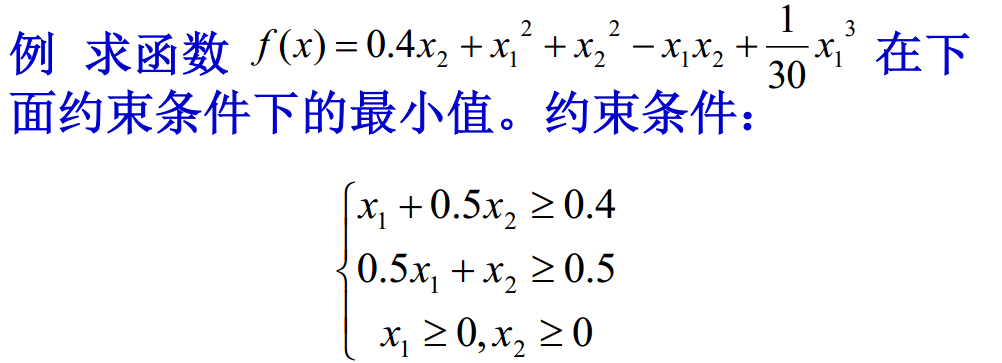

x0 = [0.5;0.5];
A = [-1,-0.5;-0.5,-1];
b = [-0.4;-0.5];
lb = [0;0];
[x,fmin] = fmincon('fx1x2',x0,A,b,[],[],lb,[])

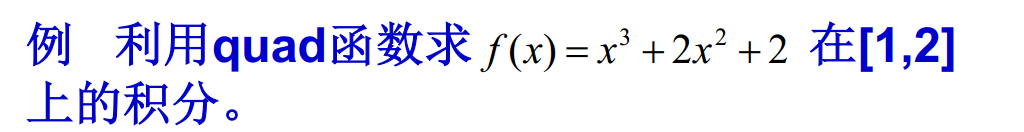

q = quad('f',1,2)
[q1, fcnt1] = quad('f', 1, 2)
% 修改tol的值
[q2, fcnt2] = quad('f',1,2,1e-8)
% 输出计算过程,quad函数
[q3, fcnt3] = quad('f',1,2,1e-8,1)

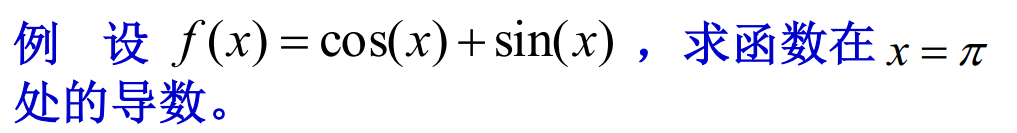

% 数据准备
x = 0:0.3:4;
y = cos(x)+sin(x);
% 用5次多项式p拟合f(x)
p = polyfit(x,y,5);
% 对拟合多项式p求导数
dp = polyder(p)

dp =    -0.0462    0.4370   -0.8618   -0.8021    0.9706


% 求dp在给定点处的函数值
dpx = polyval(dp,pi)

dpx = -1.0037

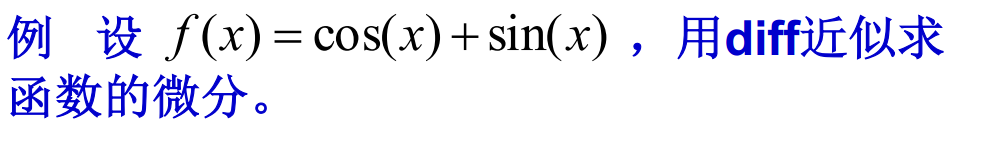

% 数据准备
x = 0:0.3:4;
y = cos(x)+sin(x);
% y的前向差分
Y = diff(y);
% x的前向差分
X = diff(x);
% 函数y=f(x)的微分近似
dy = Y./X

dy =     0.8362    0.4637    0.0499   -0.3685   -0.7539   -1.0720   -1.2943   -1.4010   -1.3825   -1.2406   -0.9878   -0.6468   -0.2481
